# The Airy Disk of a diffraction limited system

The **Airy Disk** describes the blur arising from an ideal (diffraction-limited) uniformly illuminated, circular aperture. Its name arises from the astronomer Lord Airy [(George Biddell Airy)](https://en.wikipedia.org/wiki/Airy_disk). This script exposes the code used to calculate and plot the Airy disk for diffraction limited optics.

See also: dlMTF, oiCreate; oiCompute, ieShape, ieDrawShape

Copyright ImagEval Consultants, LLC, 2010.

ieInit

## Establish an OI with diffraction limited optics

It is straightforward to calculate the diffraction limited PSF using these functions.  We explain what they do, below.

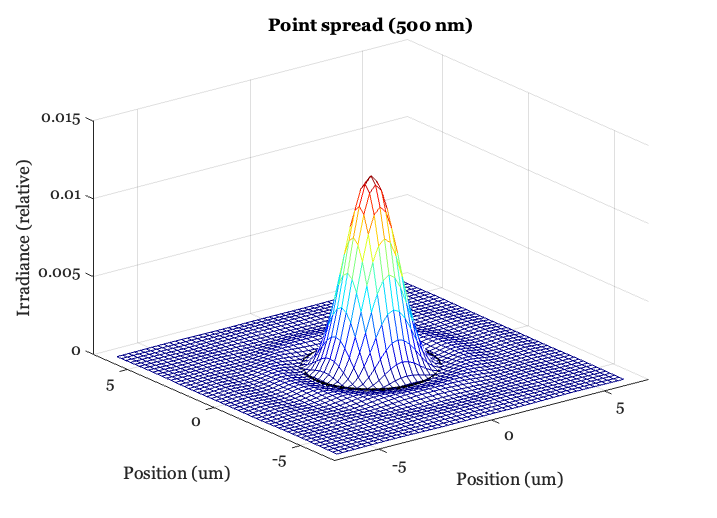

oi    = oiCreate;    % Default optics is diffraction limited, f# = 4
oiPlot(oi,'psf',[],500,'um','airydisk',true);
set(gca,'xlim',[-7 7],'ylim',[-7 7]);

## The computation

We get to choose which wavelength and the spatial sampling.  We make those choices here.

The optics contains the key optics parameters.  For diffraction limited optics that is only the f number.

optics = oiGet(oi,'optics');

nSamp    = 25;  % How many frequency samples?
thisWave = 500; % nm

% Spatial sampling units
spatialUnits = 'um';

Now we choose the frequency support for the diffraction limited optics calculation.  First we find the frequency samples that the lens supports, which the dl fsupport for this wavelength.  We specify how many frequency samples we want.

clear fSupport
val = opticsGet(optics,'dlFSupport',thisWave, spatialUnits, nSamp);
[fSupport(:,:,1),fSupport(:,:,2)] = meshgrid(val{1},val{2});


To make a smooth PSF plot, we oversample the frequency.

There are two samples at the highest frequency we plot.  So the spatial sample spacing with this frequency range is 1/(2*peakF)

**Remember: ** We specified the spatial units as cycles/micron. So the spacing is in microns.

fSupport = fSupport*4;
peakF = max(fSupport(:));
deltaSpace = 1/(2*peakF);

## Calculate the OTF using diffraction limited MTF (dlMTF)

% The dlMTF function calculates the diffraction limited MTF
otf = dlMTF(oi,fSupport,thisWave,spatialUnits);

% Calculate the psf from the OTF
psf = fftshift(ifft2(otf));

% Using deltaSpace, make the spatial support for the PSF
clear sSupport
samp = (-nSamp:(nSamp-1));
[X,Y] = meshgrid(samp,samp);
sSupport(:,:,1) = X*deltaSpace;
sSupport(:,:,2) = Y*deltaSpace;

Here is the key step.  We calculate the Airy disk from the formula

fNumber = opticsGet(optics,'fNumber');
radius = (2.44*fNumber*thisWave*10^-9)/2 * ieUnitScaleFactor(spatialUnits);

The rest is plotting. 

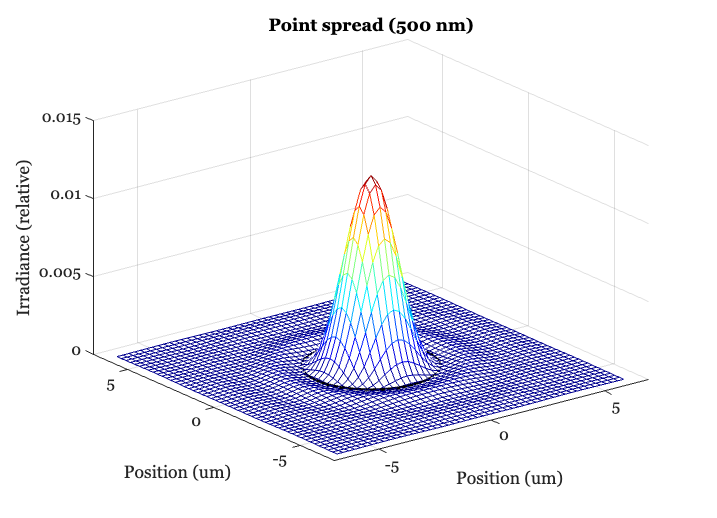

x = sSupport(:,:,1); y = sSupport(:,:,2);
ieNewGraphWin;
mesh(x,y,psf);
colormap(jet(64))

% Draw a circle at the first zero crossing (Airy disk)
nCircleSamples = 200;
[adX,adY,adZ] = ieShape('circle',nCircleSamples,radius);

% Lift the Airy disk ring up a bit so we can see it on the graph
ringZ = max(psf(:))*1e-3;
hold on; p = plot3(adX,adY,adZ + ringZ,'k-');
set(gca,'xlim',[-7 7],'ylim',[-7 7]);

set(p,'linewidth',3); hold off;
xlabel('Position (um)'); ylabel('Position (um)');
zlabel('Irradiance (relative)');
title(sprintf('Point spread (%.0f nm)',thisWave));